# **Analisi della Concentrazione di CO2 **

Questo documento mostra l'analisi della concentrazione di `CO2 `nell'atmosfera misurato nell'osservatorio di Mauna Loa. Si utilizza come input la matrice `co2.mat``,`nella quale sono memorizzate nella prima colonna i tempi di misurazione per ogni mese e nella seconda colonna i valori delle misurazioni di `CO2` . Per analizzare il fenomeno si è utilizzata la `FFT` `(Trasformata di Fourier Discreta),`vengono mostrati un grafico del comportamento del fenomeno e i relativi periodogrammi.

## Caricamento dei Dati Registrati

In questa sezione vengono caricati i dati registrati della matrice `co2.mat`, successivamente viene ricostruito il grafico del fenomeno che mostra le misurazioni registrate per ogni mese.

load -ASCII co2.mat

N.B : Attraverso il comando "load -ASCII nomefile" si effettua il caricamento del file rimuovendo elementi non idonei al problema. 

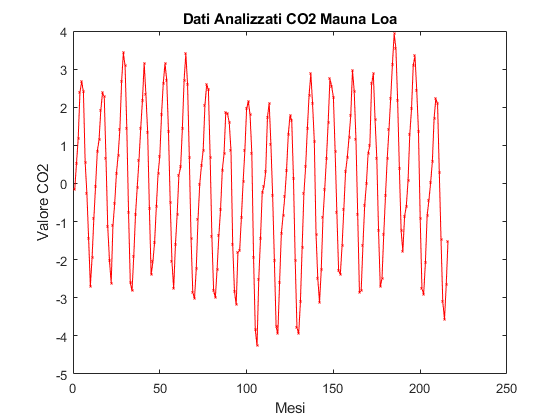

plot(co2(:,1),co2(:,2),'-xr','MarkerFaceColor','b','MarkerSize',2);
xlabel('Mesi');
ylabel('Valore CO2');
title('Dati Analizzati CO2 Mauna Loa');

##  Periodogramma del fenomeno

Si effettua la `FFT` per ottenere la trasposizione del fenomeno nel dominio delle frequenze. Successivamente si rimuove la componente continua  e viene calcolato il periodogramma relativo alla potenza sia relativo a cicli/mesi (frequenza) che mesi/ciclo(periodo). Di seguito è richiamato uno script appositamente creato che effettua i calcoli sopra espressi.

*N.B : Lo script restituisce i parametri utili per i calcoli successivi.*

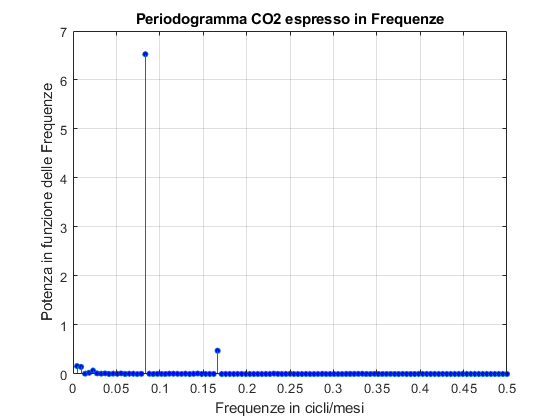

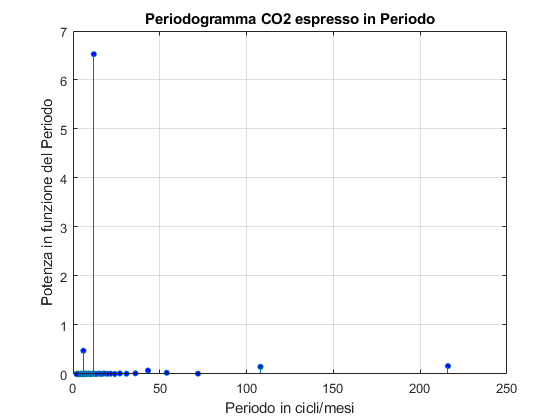

[comp_continua,potenza,freq,N,Y] = Show_Periodogram_CO2(co2);

## Calcolo dei picchi di massima potenza

Una volta ricavati i valori di potenza necessari viene determinato il picco di massima potenza ed il corrispondente indice e periodo.

%I valori di potenza sono disogranizzati, effettuo un ordinamento in senso
%decrescente
[pot_max,indice_max_pot] = sort(potenza,'descend');
pot_max(1:2) %Picchi di Potenza Massima

ans =     6.5265
    0.4748


%Indici relativi, Frequenze e Periodi
indice_max_pot(1:2)

ans =     18
    36


f1 = freq(indice_max_pot(1))

f1 = 0.0833

f2 = freq(indice_max_pot(2))

f2 = 0.1667

t1 = 1./f1

t1 = 12

t2 = 1./f2

t2 = 6

## Ricostruzione del fenomeno attraverso IDFT

## 1° Componente di Potenza Maggiore

Una volta ricavati i due picchi di massima potenza con i relativi indici, frequenze e periodi, bisogna  porre a zero tutti i termini della `DFT` tranne la `DC` e le due componenti relative alla massima potenza. Successivamente si ricostruisce il fenomeno con la `IDFT `implementata in Matlab con la  funzione `IFFT`. Di seguito verrà mostrato un confronto tra la ricostruzione e il grafico del fenomeno di partenza.

%Azzero le componenti della DFT tranne quelle relative alla potenza massima
Y(indice_max_pot(3:length(indice_max_pot)))=0;
%Per simmetria 
Y(N+1-indice_max_pot(3:length(indice_max_pot)))=0;
%Riaggiungo la componente continua alla trasformata
Y=[comp_continua;Y];
%Ricostruzione segnale con IDFT
IY=ifft(Y);
%Mostro la parte reale della trasformata
figure();
subplot(2,1,1)
plot(real(IY),'g')
title('Parte reale della Ricostruzione')

## Confronto con il grafico di partenza del Fenomeno

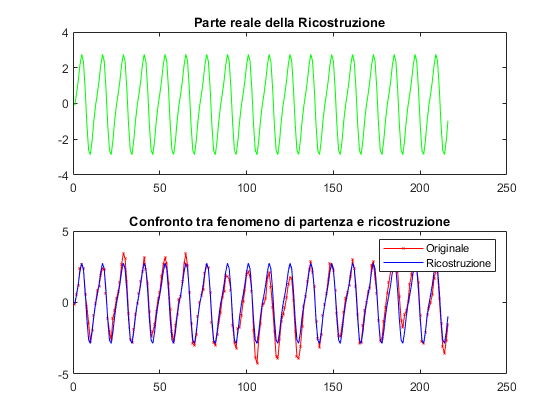

subplot(2,1,2)
plot(co2(:,1),co2(:,2),'-xr','MarkerFaceColor','b','MarkerSize',2);
hold on
plot(real(IY),'b');
hold off
legend('Originale','Ricostruzione')
title('Confronto tra fenomeno di partenza e ricostruzione')

## 2° Componente di Potenza Maggiore

Successivamente si ricostruisce il fenomeno aggiungendo anche le successive due componenti di potenza maggiore.

Y1 = fft(co2(:,2));
comp_continua2 = Y1(1);
Y1(1) = [];
Y1(indice_max_pot(5:length(indice_max_pot)))=0;
Y(N+1-indice_max_pot(5:length(indice_max_pot)))=0;
Y1=[comp_continua2;Y1];
IY1 = ifft(Y1);
figure();
subplot(2,1,1)
plot(real(IY1),'g')
title('Parte reale della Ricostruzione')

## Confronto con il grafico di partenza 

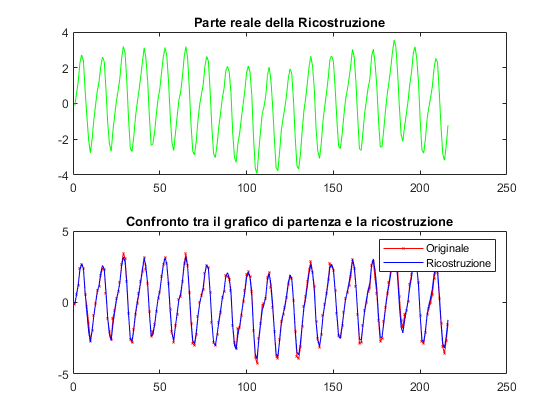

subplot(2,1,2)
plot(co2(:,1),co2(:,2),'-xr','MarkerFaceColor','b','MarkerSize',2);
hold on
plot(real(IY1),'b');
hold off
legend('Originale','Ricostruzione')
title('Confronto tra il grafico di partenza e la ricostruzione')

## Considerazioni Finali

Si nota che  il segnale ricostruito utilizzando le 4 componenti relative alle potenze massime, rappresenta meglio il segnale originale rispetto a quello ottenuto utilizzando solo le prime due componenti di potenza massima.	

## Riferimenti

- [*Docenti.unina.it D'alessio Alessandra*](https://www.docenti.unina.it/#!/professor/414c455353414e4452414427414c455353494f444c534c534e3534433630463833394e/login)

- [Trasformata di Fourier Discreta](https://it.wikipedia.org/wiki/Trasformata_discreta_di_Fourier)

## Autori

***Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936***